# **Distributed-parameter transducer model**

# **for the stepped amplitude transformer**

**2023-01-03 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

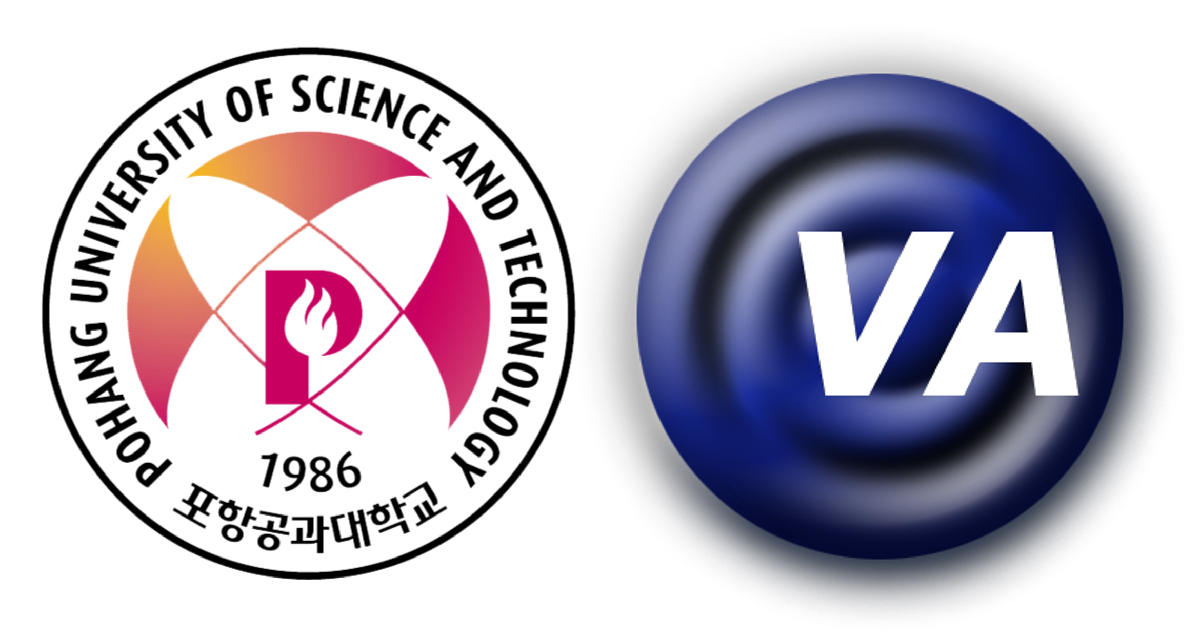

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

% Define the simulation frequency
f = 75e3;   % 75 [kHz]

% Load the material properties
mat = import_material('materials.txt');

% Define the structure
n_start = 2;    % Start index of node;
n_end   = 5;    % End index of node;
if n_start > n_end
    disp("Error: the end index of node must be greater than start index!");
    return
end
e_no    = n_end - n_start;
n_no    = e_no+1;
S = sprintf("The number of elements:    %d\n" + ...
    "The number of nodes:       %d",e_no,n_no);
disp(S);

The number of elements:    3
The number of nodes:       4


e_piezo = 2;  % Index of piezoelectric bar

% Initialize the symbols for material properties and design parameters of elements

% Mechanical
rho = sym('rho_%d', [1 n_end]); % Density
E   = sym('E_%d', [1 n_end]);   % Young's modulus
nu  = sym('nu_%d', [1 n_end]);  % Poisson ratio
c   = sym('c_%d', [1 n_end]);   % Longitudinal wave speed
k   = sym('k_%d', [1 n_end]);   % Longitudinal wave number
l   = sym('l_%d', [1 n_end]);   % Length of element
A   = sym('A_%d', [1 n_end]);   % Area of element

% Electircal
eps_33  = sym('eps_33');        % Dielectric constant, eps_33

% Mechanical-electrical
d_33    = sym('d_33');          % Piezoelectric charge constant, d_33


The effort and flow variable vectors are $F=
\left[
\matrix{
F_1\cr
F_2\cr
F_3\cr
\vdots \cr
F_{-2}\cr
F_{-1}\cr
F_0\cr
}
\right]$ and $u=
\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
\vdots \cr
u_{-2}\cr
u_{-1}\cr
u_0\cr
}
\right]$ where 1 and 0 are the node's start and end indices, and the minus sign is the reversed order from the end index.

% Initialize the symbols for effort and flow variable vectors
F   = sym('F_%d',[1 n_end]).';
u   = sym('u_%d',[1 n_end]).';
V   = sym('V');


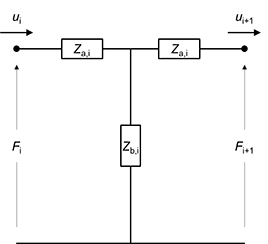

**Figure 1** The symmetric T-network circuit representation of a bar where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\frac{k_{\rm{i}} l_{\rm{i}}}{2}}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{k_{\rm{i}} l_{\rm{i}}}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{k_{\rm{i}} l_{\rm{i}}}$.

By the KCL,


$$\left[
\matrix{
F_{i}\cr
-F_{i+1}\cr
}
\right]
=
\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]
$$


% Calculating the bar's impedance for symmetric T-network
Z_b = sym('Z_b_%d',[1 n_end]);  % Z_b
Z_c = sym('Z_c_%d',[1 n_end]);  % Z_c = Z_a + Z_b
Z_d = sym('Z_d_%d',[1 n_end]);  % Z_d for the boundary conditions of both ends

for i=n_start:n_end
    Z_b(i) = -1j*rho(i)*c(i)*A(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*rho(i)*c(i)*A(i)*cot(k(i)*l(i));
end

% rho(1:n_start-1)    = [];
% c(1:n_start-1)      = [];
% k(1:n_start-1)      = [];
% l(1:n_start-1)      = [];
% A(1:n_start-1)      = [];


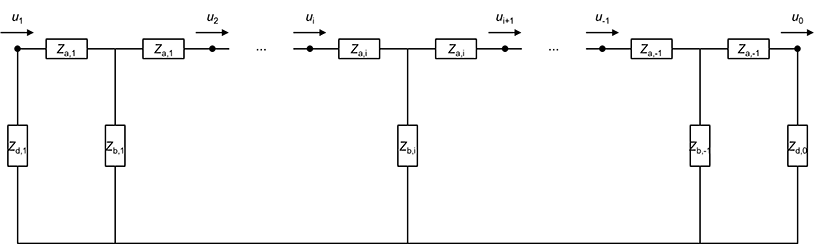

**Figure 2** The symmetric T-network circuit representation of bars mechanically connected in series and its boundary conditions of both ends

When bars are mechanically connected in series and there are the arbitrary impedances, $Z_{\rm{d}}$, at both ends without external force, $F=Z \cdot u=[0]$.

And the impedance matrix is $Z=
\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & \cdots & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} &  \cdots & 0 & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & \cdots & 0 & 0 & 0 \cr
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots & \vdots \cr
0 & 0 & 0 & \cdots & Z_{\rm{c,-3}}+Z_{\rm{c,-2}} & -Z_{\rm{b,-2}} & 0 \cr
0 & 0 & 0 & \cdots & -Z_{\rm{b,-2}} & Z_{\rm{c,-2}}+Z_{\rm{c,-1}} & -Z_{\rm{b,-1}} \cr
0 & 0 & 0 & \cdots & 0 & -Z_{\rm{b,-1}} & Z_{\rm{c,0}}+Z_{\rm{d,0}} \cr
}
\right]$ where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\frac{k_{\rm{i}} l_{\rm{i}}}{2}}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{k_{\rm{i}} l_{\rm{i}}}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{k_{\rm{i}} l_{\rm{i}}}$.

% Constructing the impedance matrix
Z = sym('Z_%d_%d',[n_end n_end]);

Z(n_start,n_start)          = Z_c(n_start) + Z_d(n_start);
Z(n_start,n_start+1)        = -Z_b(n_start);
Z(n_start,n_start+2:n_end)  = 0;

for i=n_start+1:n_end-1
    Z(i,n_start:i-2)  = 0;
    Z(i,i-1)    = -Z_b(i-1);
    Z(i,i)      = sum(Z_c(i:i+1));
    Z(i,i+1)    = -Z_b(i);
    Z(i,i+2:n_end)= 0;
end

Z(n_end, n_start:n_end-2) = 0;
Z(n_end, n_end-1)   = -Z_b(n_end-1);
Z(n_end, n_end)     = Z_c(n_end) + Z_d(n_end);


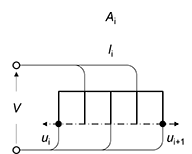

**Figure 3** 4 Piezoelectric bars mechanically connected in series and electrically in parallel

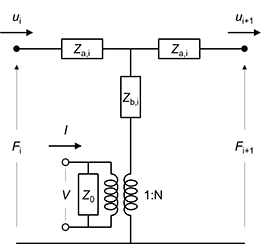

**Figure 4** The symmetric T-network circuit representation of piezoelectric bars mechanically connected in series and electrically in parallel

By KCL,

$\left[
\matrix{
F_{i}-NV\cr
-F_{i+1}+NV\cr
}
\right]
=
\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]$where $N=\frac{A_{i} \thinspace d_{33}}{l_{i} \thinspace s_{33}^{E}}$

N = A(e_piezo)*d_33/(l(e_piezo)*E(e_piezo));

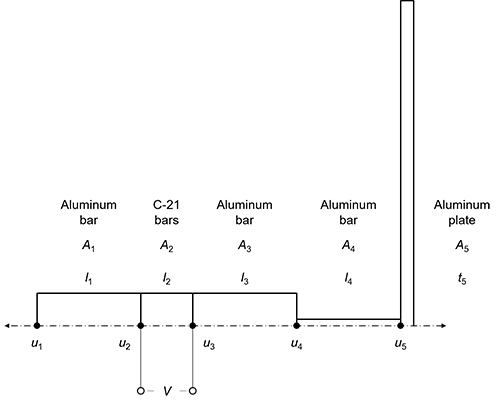

**Figure 5** Typical stepped-plate transducer

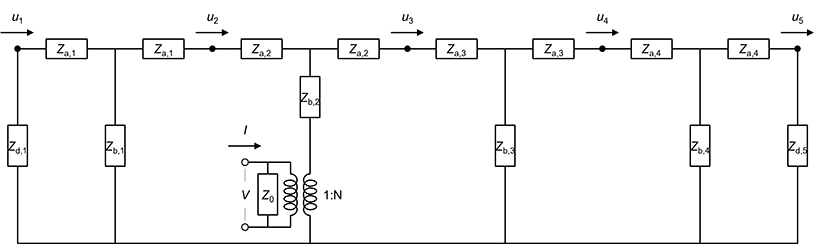

**Figure 6 **The distributed network representation of typical stepped-plate transudcer

By KCL,


$$\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & -Z_{\rm{b,3}} & 0 \cr
0 & 0 & -Z_{\rm{b,3}} & Z_{\rm{c,3}}+Z_{\rm{c,4}} & -Z_{\rm{b,4}} \cr
0 & 0 & 0 & -Z_{\rm{b,4}} & Z_{\rm{c,5}}+Z_{\rm{d,5}} \cr
}
\right]

\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
u_4\cr
u_5\cr
}
\right]

=

\left[
\matrix{
0\cr
-NV\cr
NV\cr
0\cr
0\cr
}
\right]$$


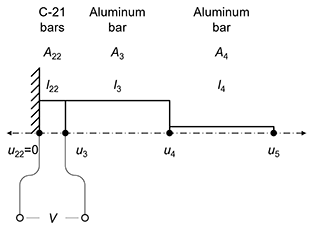

**Figure 7** The aluminum stepped amplitude transformer driven by two piezoelectric bars, C-21, fixed on one end and free on the other end

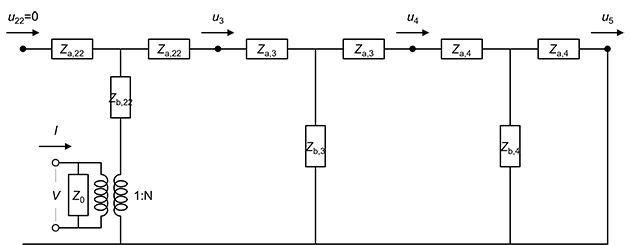

**Figure 8** The distributed network representation of the aluminum stepped amplitude transformer driven by piezoelectric bars

% The stepped amplitude transformer

% Applying the volume conditions as material properties

% Define the bounrady conditions of both ends
Z = subs(Z, [Z_d(n_start) Z_d(end)], [Inf 0]);
Z(1:n_start-1,:)    = [];
Z(:,1:n_start-1)    = [];
Z

$$Z = \begin{array}{l} \left(\begin{array}{cccc} \infty -A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i} & \sigma_{3} & 0 & 0\\ \sigma_{3} & -A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}-\sigma_{5} & \sigma_{2} & 0\\ 0 & \sigma_{2} & -\sigma_{5}-\sigma_{4} & \sigma_{1}\\ 0 & 0 & \sigma_{1} & -\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=A_{5}\,c_{5}\,\rho_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\\ \sigma_{5}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i} \end{array}$$

% Define the boundary conditions
u = subs(u, u(n_start), 0);
u(1:n_start-1)  = [];
u

$$u = \left(\begin{array}{c} 0\\ u_{3}\\ u_{4}\\ u_{5} \end{array}\right)$$

F = subs(F, F(1:e_piezo-1), zeros(e_piezo-1,1));
F = subs(F, F(e_piezo), -N*V);
F = subs(F, F(e_piezo+1), N*V);
F = subs(F, F(e_piezo+2:end), zeros(n_end - e_piezo - 1,1));
F(1:n_start-1)  = [];
F

$$F = \left(\begin{array}{c} -\frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}}\\ \frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}}\\ 0\\ 0 \end{array}\right)$$


eqn = Z*u == F

$$eqn = \begin{array}{l} \left(\begin{array}{c} \frac{A_{2}\,c_{2}\,\rho_{2}\,u_{3}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}=-\sigma_{2}\\ -u_{3}\,\left(A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}+\sigma_{1}\right)+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{4}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}=\sigma_{2}\\ -u_{4}\,\left(\sigma_{1}+A_{5}\,c_{5}\,\rho_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\right)+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{5}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0\\ -A_{5}\,c_{5}\,\rho_{5}\,u_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{2}=\frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}} \end{array}$$

u(2) = solve(eqn(1),u(2))

$$u = \left(\begin{array}{c} 0\\ \frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ u_{4}\\ u_{5} \end{array}\right)$$

eqn1 = Z*u == F

$$eqn1 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{2}=-\sigma_{2}\\ \frac{A_{3}\,c_{3}\,\rho_{3}\,u_{4}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}-\frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\left(A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}+\sigma_{1}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}=\sigma_{2}\\ -u_{4}\,\left(\sigma_{1}+A_{5}\,c_{5}\,\rho_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\right)-\frac{A_{3}\,V\,c_{3}\,d_{33}\,\rho_{3}\,\sin\left(k_{2}\,l_{2}\right)}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}\,\sin\left(k_{3}\,l_{3}\right)}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{5}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0\\ -A_{5}\,c_{5}\,\rho_{5}\,u_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{2}=\frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}} \end{array}$$

u(3) = solve(eqn1(2),u(3))

$$u = \left(\begin{array}{c} 0\\ \frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ -\frac{\sin\left(k_{3}\,l_{3}\right)\,\left(\frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}}+\frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\left(A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}+A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\right)\,\mathrm{i}}{A_{3}\,c_{3}\,\rho_{3}}\\ u_{5} \end{array}\right)$$

eqn2 = Z*u == F

$$eqn2 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{2}=-\sigma_{2}\\ \sigma_{2}=\sigma_{2}\\ -\frac{A_{3}\,V\,c_{3}\,d_{33}\,\rho_{3}\,\sin\left(k_{2}\,l_{2}\right)}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}\,\sin\left(k_{3}\,l_{3}\right)}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{5}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}+\frac{\sin\left(k_{3}\,l_{3}\right)\,\sigma_{1}\,\left(\sigma_{3}+A_{5}\,c_{5}\,\rho_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\right)\,\mathrm{i}}{A_{3}\,c_{3}\,\rho_{3}}=0\\ -A_{5}\,c_{5}\,\rho_{5}\,u_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}+\frac{A_{4}\,c_{4}\,\rho_{4}\,\sin\left(k_{3}\,l_{3}\right)\,\sigma_{1}}{A_{3}\,c_{3}\,\rho_{3}\,\sin\left(k_{4}\,l_{4}\right)}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+\frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\left(A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}+\sigma_{3}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ \sigma_{2}=\frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}}\\ \sigma_{3}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i} \end{array}$$

u(4) = solve(eqn2(3),u(4))

$$u = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ -\frac{\sin\left(k_{3}\,l_{3}\right)\,\sigma_{1}\,\mathrm{i}}{A_{3}\,c_{3}\,\rho_{3}}\\ \frac{\sin\left(k_{4}\,l_{4}\right)\,\left(-\frac{A_{3}\,V\,c_{3}\,d_{33}\,\rho_{3}\,\sin\left(k_{2}\,l_{2}\right)}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}\,\sin\left(k_{3}\,l_{3}\right)}+\frac{\sin\left(k_{3}\,l_{3}\right)\,\sigma_{1}\,\left(\sigma_{2}+A_{5}\,c_{5}\,\rho_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\right)\,\mathrm{i}}{A_{3}\,c_{3}\,\rho_{3}}\right)\,\mathrm{i}}{A_{4}\,c_{4}\,\rho_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}}+\frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\left(A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}+\sigma_{2}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ \sigma_{2}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i} \end{array}$$

u = subs(u, [A(3), A(4)],[A(2) A(2)]);
u = subs(u, [c(4) c(5)], [c(3), c(3)]);
u = subs(u, [k(4) c(5)], [k(3), k(3)]);
u = subs(u, [rho(4) rho(5)], [rho(3), rho(3)])

$$u = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ -\frac{\sin\left(k_{3}\,l_{3}\right)\,\sigma_{1}\,\mathrm{i}}{A_{2}\,c_{3}\,\rho_{3}}\\ \frac{\sin\left(k_{3}\,l_{4}\right)\,\left(-\frac{A_{2}\,V\,c_{3}\,d_{33}\,\rho_{3}\,\sin\left(k_{2}\,l_{2}\right)}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}\,\sin\left(k_{3}\,l_{3}\right)}+\frac{\sin\left(k_{3}\,l_{3}\right)\,\sigma_{1}\,\left(\sigma_{2}+A_{5}\,c_{3}\,\rho_{3}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\right)\,\mathrm{i}}{A_{2}\,c_{3}\,\rho_{3}}\right)\,\mathrm{i}}{A_{2}\,c_{3}\,\rho_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{2}\,V\,d_{33}}{E_{2}\,l_{2}}+\frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\left(A_{2}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}+\sigma_{2}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ \sigma_{2}=A_{2}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{4}\right)\,\mathrm{i} \end{array}$$

% Compute simplified symbolic expression
simplifiedExpr = simplify(u,"Steps",400)

$$simplifiedExpr = \left(\begin{array}{c} 0\\ \frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}}\\ -\frac{V\,d_{33}\,\sin\left(k_{3}\,l_{3}\right)\,\mathrm{i}}{E_{2}\,c_{3}\,l_{2}\,\rho_{3}}+\frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\sin\left(k_{3}\,l_{3}\right)\,\left(c_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}+c_{3}\,\cot\left(k_{3}\,l_{4}\right)\,\mathrm{i}\right)}{E_{2}\,c_{2}\,c_{3}\,l_{2}\,\rho_{2}}\\ -\frac{V\,d_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\sin\left(k_{3}\,l_{4}\right)\,\mathrm{i}}{E_{2}\,c_{2}\,l_{2}\,\rho_{2}\,\sin\left(k_{3}\,l_{3}\right)}+\frac{V\,d_{33}\,\sin\left(k_{3}\,l_{3}\right)\,\sin\left(k_{3}\,l_{4}\right)\,\left(A_{2}\,\cot\left(k_{3}\,l_{4}\right)\,\mathrm{i}+A_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\right)\,\left(c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\sin\left(k_{2}\,l_{2}\right)-c_{2}\,\rho_{2}+c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{4}\right)\,\sin\left(k_{2}\,l_{2}\right)\right)}{A_{2}\,E_{2}\,c_{2}\,c_{3}\,l_{2}\,\rho_{2}\,\rho_{3}} \end{array}\right)$$